# 5G Channel Sounding with Doppler

## 3GPP NR channel model

fc = 28e9;    % carrier in Hz
dlySpread = 50e-9;  % delay spread in seconds
chan = nrCDLChannel('DelayProfile','CDL-C',...
    'DelaySpread',dlySpread, 'CarrierFrequency', fc, ...
    'NormalizePathGains', true);
chaninfo = info(chan);


gain  = chaninfo.AveragePathGains;


aoaAz = chaninfo.AnglesAoA;

%  elevation angle of arrival

aoaEl  = 90 - chaninfo.AnglesZoA;

%    azimuth angle of departure
aodAz = chaninfo.AnglesAoD;

%    elevation angle of departure 
aodEl = 90 - chaninfo.AnglesZoD;


dly = chaninfo.PathDelays;



npath = length(dly)

npath = 24

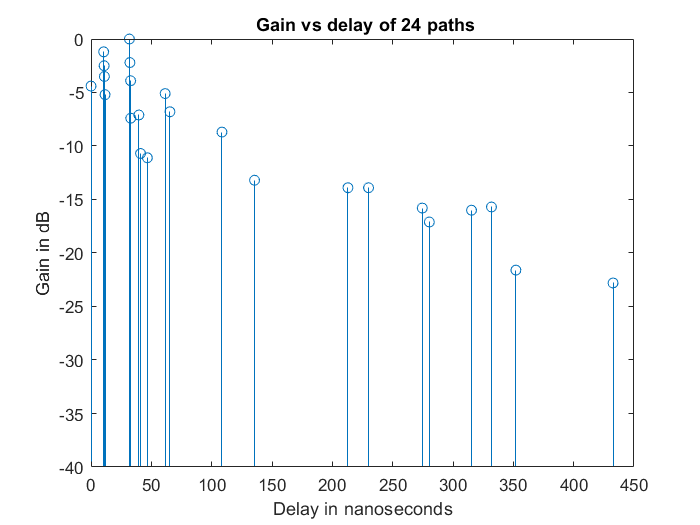


% plotting gain vs delay

stem(1e9*dly,gain,"BaseValue",-40)
xlabel('Delay in nanoseconds')
ylabel('Gain in dB')
title(' Gain vs delay of 24 paths')

## Patch Element

% Constants
vp = physconst('lightspeed');  % speed of light
lambda = vp/fc;   % wavelength

%  patch element
len = 0.49*lambda;
groundPlaneLen = lambda;
ant = patchMicrostrip(...
    'Length', len, 'Width', 1.5*len, ...
    'GroundPlaneLength', groundPlaneLen, ...
    'GroundPlaneWidth', groundPlaneLen, ...
    'Height', 0.01*lambda, ...
    'FeedOffset', [0.25*len 0]);


ant.Tilt = 90;
ant.TiltAxis = [0 1 0];

## Creating  UE and gNB antennas

used a class file ElemWithAxes with different methods to manipulate the antennas


elemUE = ElemWithAxes(fc,ant);
elemgNB = ElemWithAxes(fc,ant);

## Rotate the UE and gNB antennas

Aligning to the strongest  path 



% Finding  the index of the path with the maximum gain.

index = find(gain == max(gain));

%  Calling  the elemUE.alignAxes() methods to align the UE antenna
% to the angle of arrival corresponding to the strongest path

alignAxes(elemUE,aoaAz(index),aoaEl(index));

% for angle of departure

alignAxes(elemgNB,aodAz(index),aodEl(index));

## Get the directivity along the paths

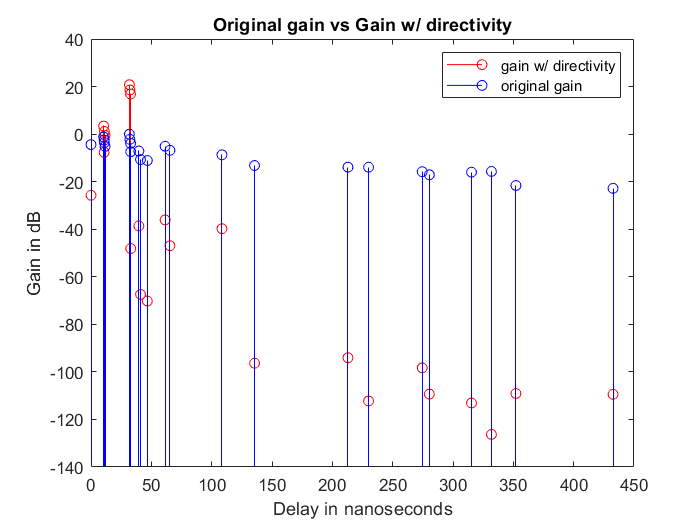


%  Calling the elemUE.step() method with the angles of arrivals of the
% paths to get the directivity of the paths on the UE antenna.

dirUE  = elemUE.step(aoaAz,aoaEl);

dirgNB  = elemgNB.step(aodAz,aodEl);



gainDir = gain + dirUE + dirgNB;

%plotting to see the effect of rotation

figure;

stem(1e9*dly,gainDir,"BaseValue",-140,'color','r')
hold on 
stem(1e9*dly,gain,"BaseValue",-140,"Color",'b')
hold off
legend("gain w/ directivity","original gain")
title("Original gain vs Gain w/ directivity")
xlabel('Delay in nanoseconds')
ylabel('Gain in dB')

## Computing the Doppler



vkmh = 100*5/18;
elemUE.set('vel',[0 vkmh 0]);

% calling the methos already defined

dop = doppler(elemUE,aoaAz,aoaEl);

## Transmitting a channel sounding signal

fsamp = 4*120e3*1024;  % sample rate in Hz
nfft = 1024;           % number of samples per frame = FFT window
nframe = 512;          % number of frames

In frequency-domain channel sounding we create the TX samples in frequency domain. 

% generating the symbols from bits 

x0_fd = qammod(randi([0 1],nfft*2,1),4,'InputType','bit','UnitAveragePower',true);


x0 = ifft(x0_fd);

x0_rep = repmat(x0,nframe,1);

## Create a multi-path channel object

To simulate the multi-path channel, I have a class , `SISOMPChan`. 

% Using the class to create the channel 

chan1 = SISOMPChan('dly',dly,'fsamp',fsamp,'dop',dop,'gain',gainDir);

## Implementing the channel

%  Run the data through the step method 

y = step(chan1,x0_rep);



gain_y = pow2db(abs(y).^2);

% creating random noise

noise = db2pow(gain_y - 20).*exp(1i*randn((nfft*nframe),1));

% adding the noise to output

ynoisy = y + noise;

## Estimating the channel in frequency domain

reshaping and getting the received in frequnecy domain 



yshape = reshape(ynoisy,[nfft,nframe]);

yfd = fft(yshape,1024,1);


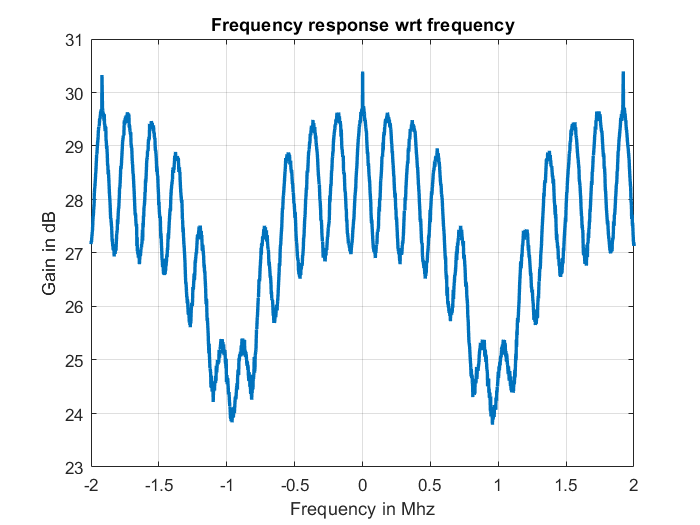


% estimating the frequnecy domain channel 

hestFd =zeros(nfft,nframe);


    for j = 1:nframe
        
        hestFd(:,j) = yfd(:,j)./x0_fd;
    end


fresp = reshape(hestFd,[nfft*nframe,1]);

% Plotting  the estimated channel magnitude in dB.  Label the axes in
% time and frequency

f = linspace(-fsamp*1e-6,1e-6*fsamp,nframe*nfft);
plot(f,pow2db(abs(fresp).^2),"LineStyle","-","LineWidth",2)
title("Frequency response wrt frequency")
ylabel("Gain in dB")
xlabel("Frequency in Mhz")
xlim([-2 2])
grid on

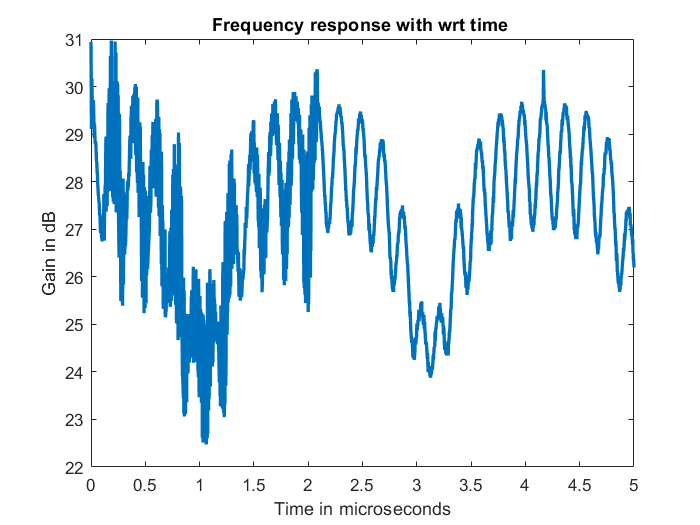



t = linspace(0,1e6*nframe*nfft/fsamp,nframe*nfft);
plot(t,pow2db(abs(fresp).^2),"LineStyle","-","LineWidth",2)
title("Frequency response with wrt time ")
ylabel("Gain in dB")
xlabel("Time in microseconds")
xlim([0 5])

## Estimating the channel in time-domain

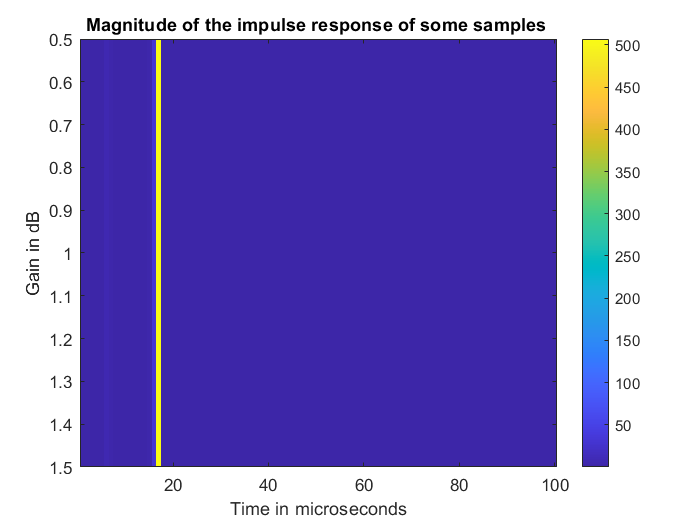

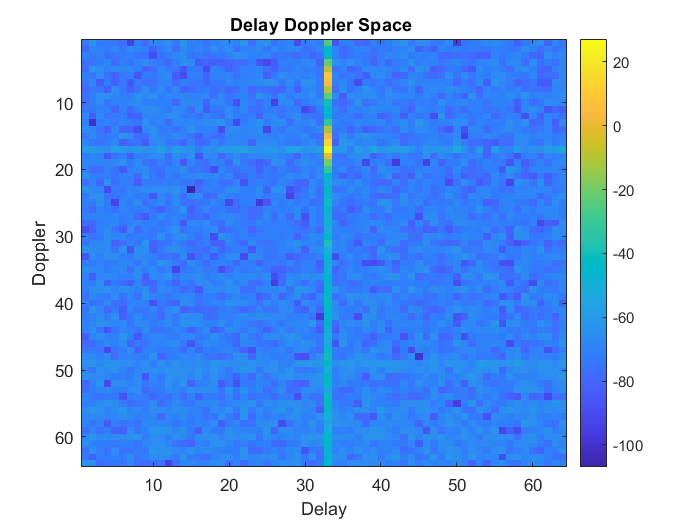

% getting back in time domain 
hest = ifft(hestFd);


t = linspace(0,1e9*nframe*nfft/fsamp,nframe*nfft);
imagesc(abs(hest(1:100)).^2)
colorbar
title("Magnitude of the impulse response of some samples ")
ylabel("Gain in dB")
xlabel("Time in microseconds")